clear
tspan = [0 100];

%定常値を設定
%{
judge ok!

安定　条件clear
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
% W が単調減少する特異的な error ?
error = [1;1;1;0;0;0;1;1;1];

安定じゃない
steady_delta = [-0.2607;0.6415;0.4656];
steady_deltaomega = [0;0;0];
steady_E = [4.3303;3.2225;2.2370];

ぎり安定
steady_delta = [-1.25664;0;0];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

不安定
steady_delta = [0.942478;0;-1.41372];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

めちゃ安定?
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

% W が単調減少する ->
error = [0;0;0;0;0;0;0.1;-0.1;-0.1];
% slackで送ったもの -> 
error = [0.01;0;0;0;0;0;0.1;-0.1;-0.1];
% 条件clear　W良さげ -> 
error = [0;0;0.0001;0;0;0;0.1;-0.1;-0.1];
% 条件clearだけどすんごい揺れる -> 
error = [0;0;0.01;0;0;0;0;0;0];


% W 良さげ　条件clear
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
error = [0.01;0;0;0;0;0;0.1;-0.1;-0.1];

% W 良さげ　条件clear
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0;0.0001;0;0;0;0.1;-0.1;-0.1];


% 条件clear なのに W だめ
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
error = [0;0;0.1;0;0;0;0;0;0];

%}

% Ured_G, W_F, Wred_G, W_F + Wred_G のグラフを表示するなら 1 . 表示しないなら 0.
flag_accum = 1;

% diff( W_F + Wred_G ) のグラフを表示するなら 1 . 表示しないなら 0.
flag_accum_diff = 1;

steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
error = [0.01;0;0;0;0;0;0.1;-0.1;-0.1];


steady_generator_state = [steady_delta; steady_deltaomega; steady_E];

initial_generator_state = steady_generator_state + error;

judge_steady(initial_generator_state)

Matrix: psi is steady.
Matrix: A is steady.
Kernel of Matrix:B is span{1}.
Kernel of Matrix:L is span{1}.
Matrix: Lo=L-C*inv(A)*B　is symmetric positive definite.


judge_steady(steady_generator_state)

Matrix: psi is steady.
Matrix: A is steady.
Kernel of Matrix:B is span{1}.
Kernel of Matrix:L is span{1}.
Matrix: Lo=L-C*inv(A)*B　is symmetric positive definite.


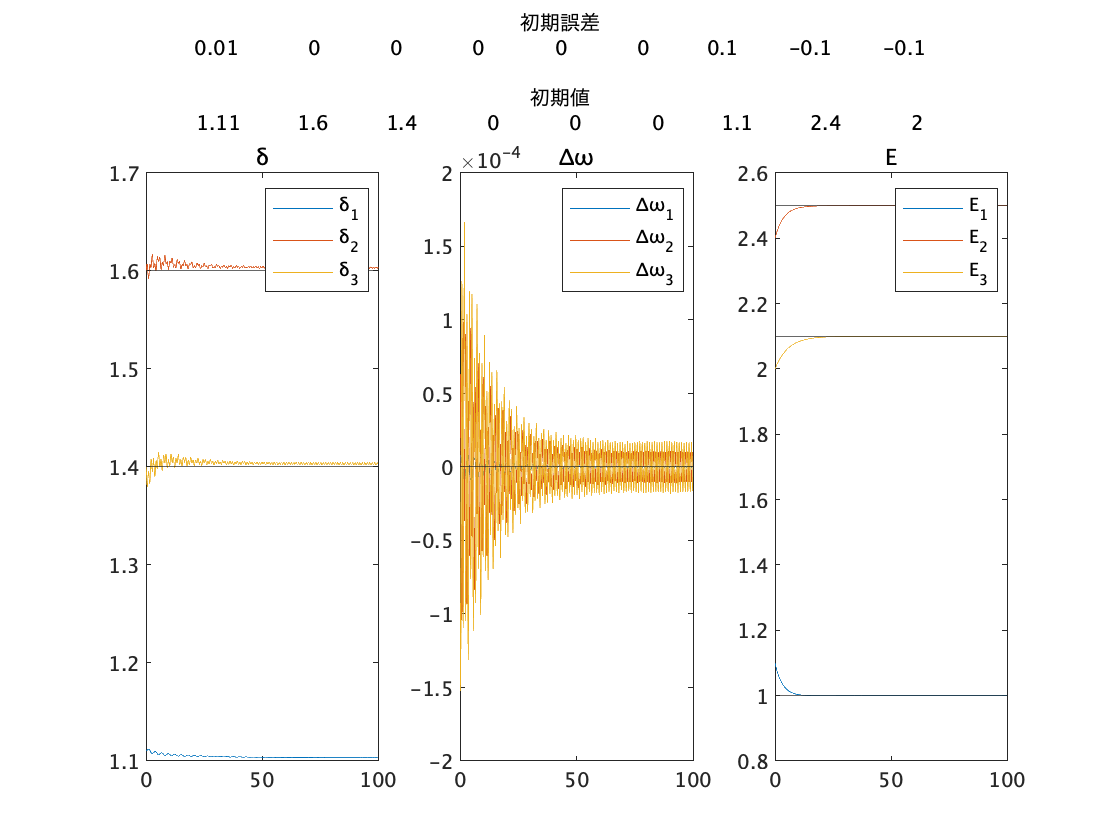

Ured_G_star = 13.7543

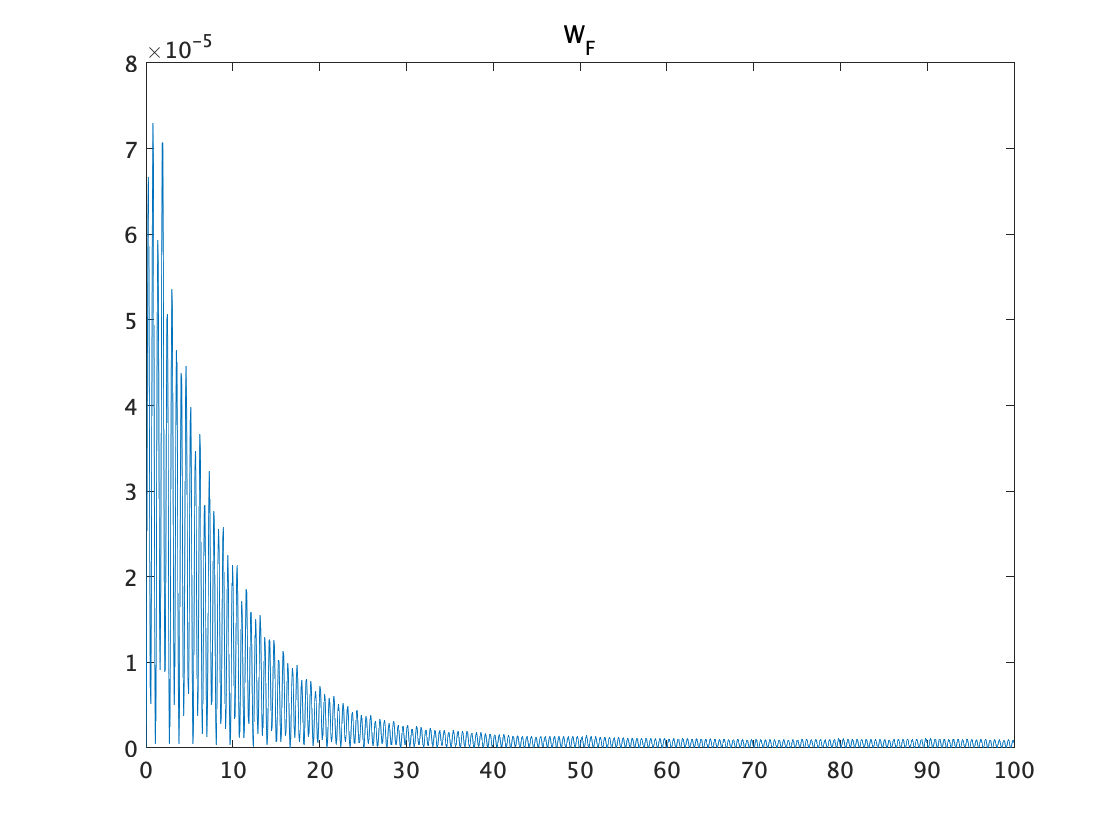

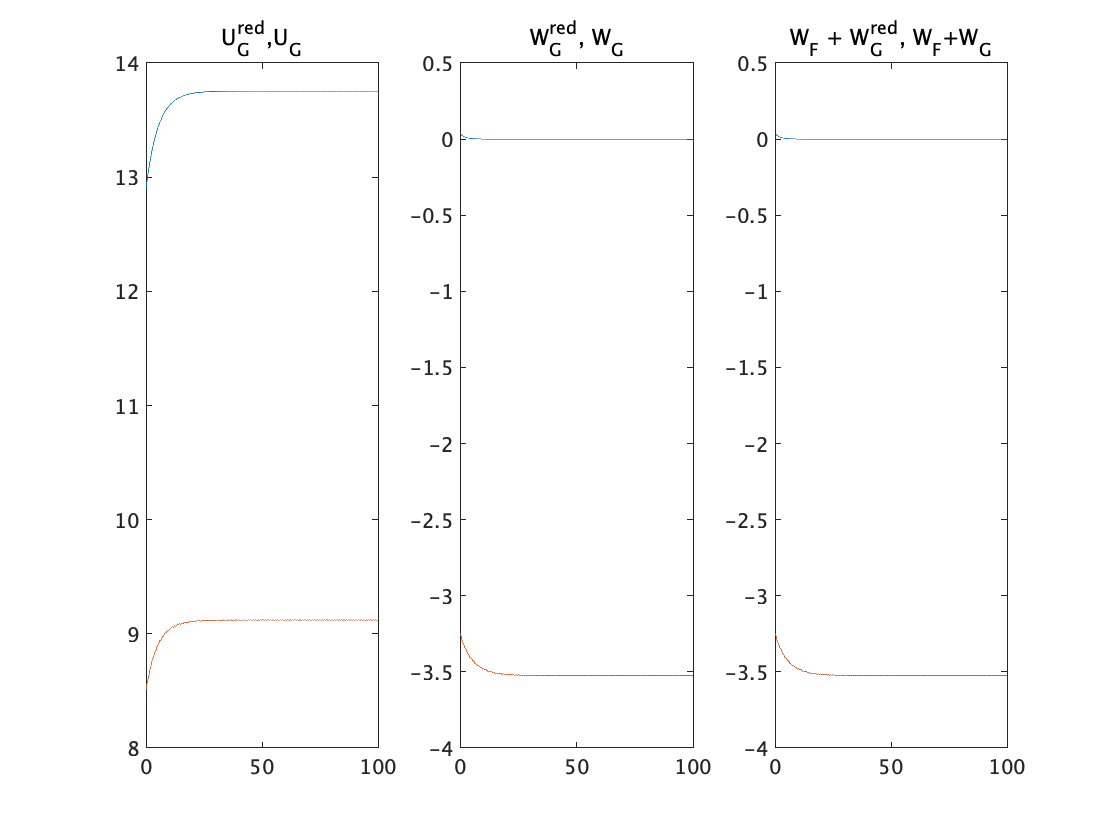

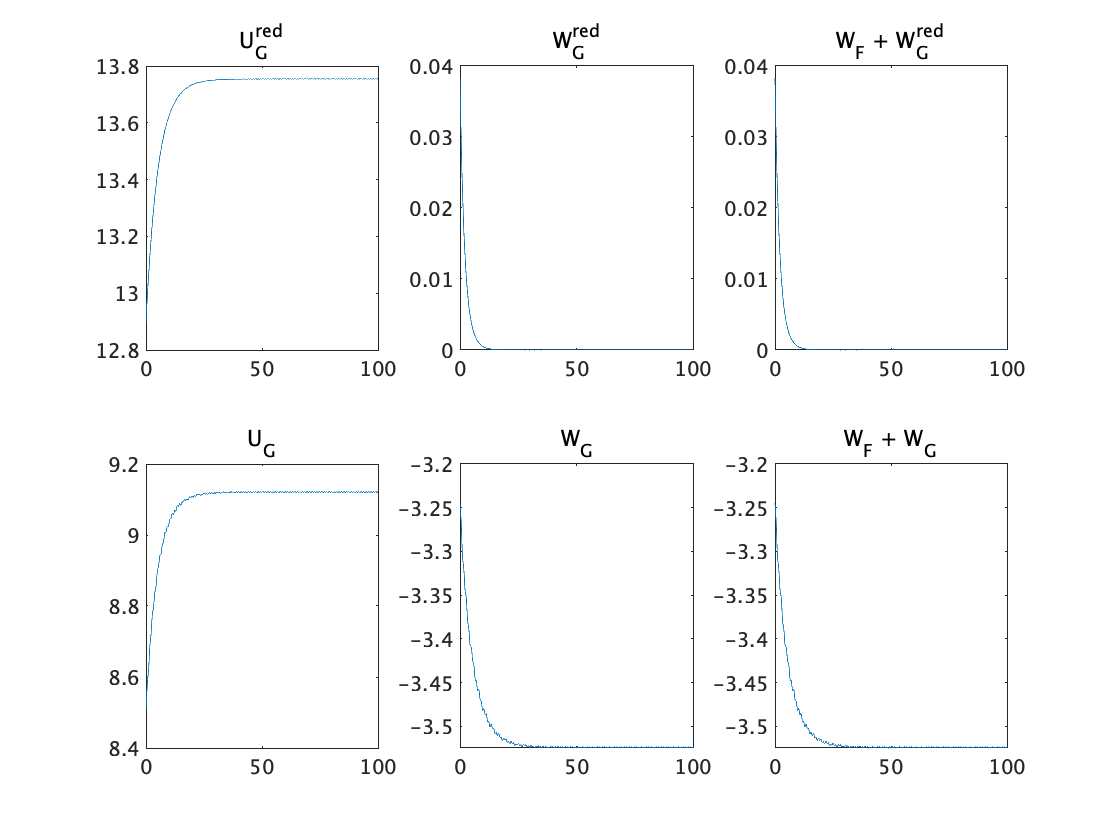

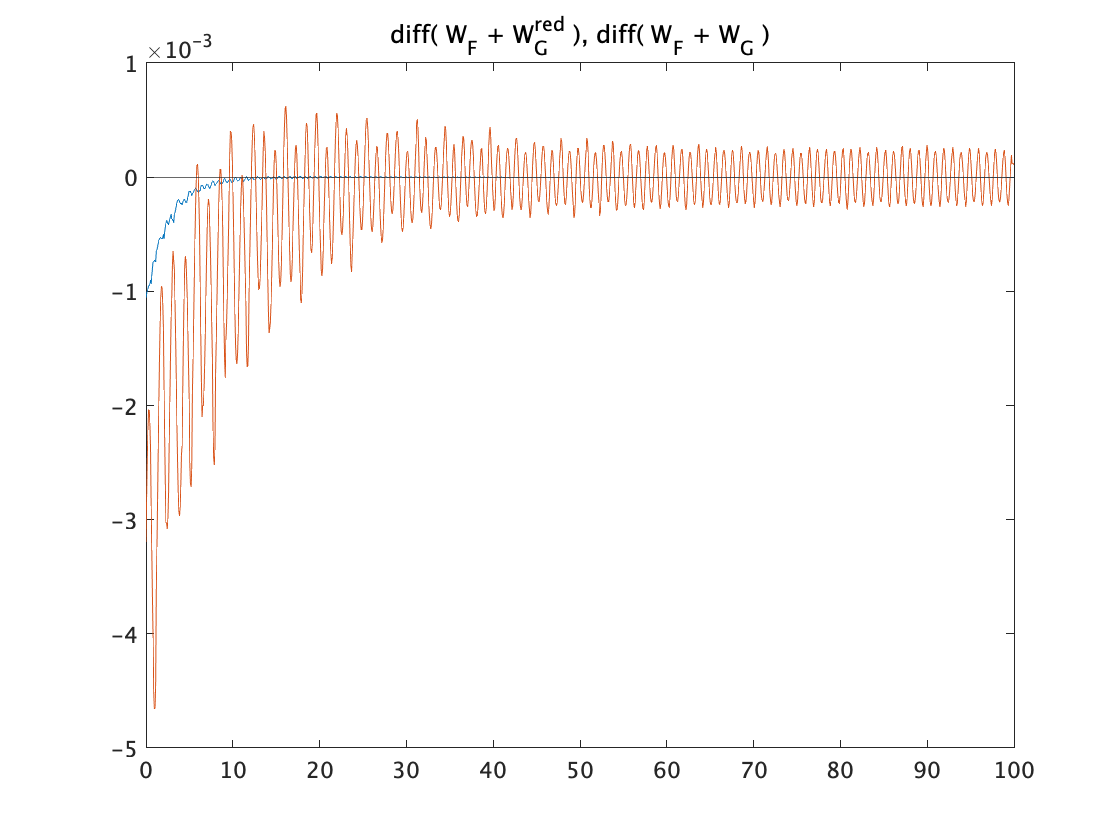

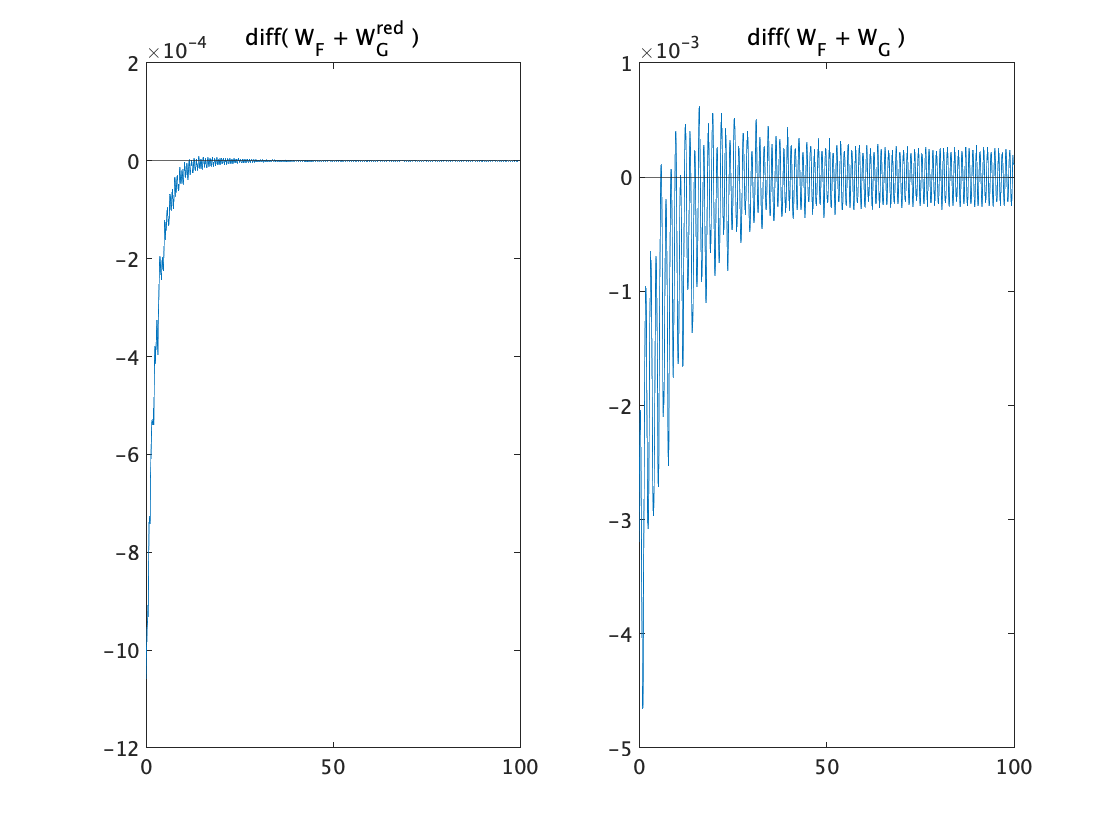

max_diff_W_FGred = 8.6087e-06

max_diff_W_FG = 6.2387e-04


plot_generator_state_wrap = @(error,initial_generator_state) plot_generator_state(error,tspan,initial_generator_state,steady_generator_state,flag_accum,flag_accum_diff);

figure;
plot_generator_state_wrap(error,initial_generator_state);



%figure;
%f = fit(t_U(:,1),t_U(:,2),'poly4');
%syms x f1(x) diff2_f1(x)
%f1(x) = f.p1*x^4 + f.p2*x^3 + f.p3*x^2 + f.p4*x + f.p5;
%diff2_f1(x) = diff(f1,2);
%diff2_f1(1:10)  %任意のxで W(x)>=0 
%F = solve(diff2_f1 == 0, x)  %かつ、これが複素数なら蓄積関数WはRealな解を持たなくて、半正定関数

%plot(f,t_U(:,1),t_U(:,2))
